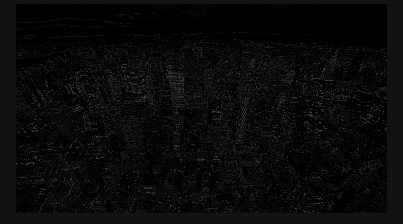

clear
%set up test vector file
file = fopen("sobel_test_vector.txt", "W");
fprintf(file, "%5s %5s %5s %5s  %7s %7s %7s  %7s %7s %7s  %7s %7s %7s  %7s %7s %7s  %7s %7s\n", ...
                "pxl", "valid", "x_i", "y_i", ...
                "sw(1,1)", "sw(1,2)", "sw(1,3)", ...
                "sw(2,1)", "sw(2,2)", "sw(2,3)", ...
                "sw(3,1)", "sw(3,2)", "sw(3,3)", ...
                "win_vld", "gx_q", "gy_q", ...
                "mag_o", "mag_vld");
fmt = "%5d %5d %5d %5d  %7d %7d %7d  %7d %7d %7d  %7d %7d %7d  %7d %7d %7d  %7d %7d\n";

%open image file
rgb_img = imread("img_1080p.jpg");

%rgb to grey scale
grey = gray_scale(rgb_img);
[height, width] = size(grey);

% allocate mem for edge scale image
edge = uint8(zeros(size(grey)));

%inputs for RTL sim
pixel_valid_i = 1;

%constants
horiz_kernel = [1, 0, -1; % horizontal kernel
                2, 0, -2;
                1, 0, -1];
vert_kernel = [ 1,  2,  1; % vertical kernel
                0,  0,  0;
               -1, -2, -1];

% ----------- line buffer memories ----------------- %
line_delay0 = zeros(1, width);
line_delay1 = zeros(1, width);

% ----------- pipeline registers, mirror the RTL ----------------- %
% *_q is the register value after the current clock edge
% *_d is the value it takes on the next clock edge

% line buffer BRAM read registers and the input delayed to match them
tap0_q        = 0;  % pixel_line_buff tap0_r
tap1_q        = 0;  % pixel_line_buff tap1_r
pixel_q       = 0;  % greyscale_pixel_r
x_q           = 0;  % x_r, one based
y_q           = 0;  % y_r, one based
pixel_valid_q = 0;  % pixel_valid_r

window_q       = zeros(3,3); % pixel_line_buff window_r
window_valid_q = 0;          % pixel_line_buff window_valid_o
gx_q           = 0;          % sobel_filter gx_r
gy_q           = 0;          % sobel_filter gy_r
stage1_valid_q = 0;          % sobel_filter stage1_valid_r
mag_q          = 0;          % sobel_filter mag_r, before the output shift
stage2_valid_q = 0;          % sobel_filter stage2_valid_r = mag_valid_o

% pixel coordinates carried down the pipeline, only for the preview image
yx_q  = [0 0];  % newest pixel in window_q
yx1_q = [0 0];  % lined up with stage 1
yx2_q = [0 0];  % lined up with stage 2

for y_i = 1:height
    for x_i = 1:width
        if pixel_valid_i == 1
            grey_pixel_i = double(grey(y_i, x_i));

            % ---------- line buffer BRAMs, read data is registered ----------
            % line buffer 0: read-first, read and write at the current x
            tap0_d = line_delay0(1, x_i);
            line_delay0(1, x_i) = grey_pixel_i;

            % line buffer 1: read at the current x,
            % write last clock's tap0 at last clock's x
            tap1_d = line_delay1(1, x_i);
            if pixel_valid_q
                line_delay1(1, x_q) = tap0_q;
            end

            % ---------- next-state logic, uses only current *_q values ----------

            % pixel_line_buff: shift in the delayed pixel and registered taps,
            % valid comes from the delayed x and y, same as the RTL
            if pixel_valid_q
                window_d       = [window_q(:, 2:3), [tap1_q; tap0_q; pixel_q]];
                window_valid_d = double(x_q >= 3 && y_q >= 3);
            else
                window_d       = window_q;
                window_valid_d = 0;
            end
            yx_d = [y_q, x_q];

            % sobel stage 1: convolve the window that is in the register now
            if window_valid_q
                gx_d = sum(sum(window_q .* horiz_kernel));
                gy_d = sum(sum(window_q .* vert_kernel));
            else
                gx_d = gx_q; % RTL holds gx_r and gy_r when not valid
                gy_d = gy_q;
            end
            stage1_valid_d = window_valid_q;
            yx1_d          = yx_q;

            % sobel stage 2: Manhattan magnitude, zero when not valid
            if stage1_valid_q
                mag_d = abs(gx_q) + abs(gy_q);
            else
                mag_d = 0;
            end
            stage2_valid_d = stage1_valid_q;
            yx2_d          = yx1_q;

            % ---------- clock edge: every register updates at once ----------
            tap0_q   = tap0_d;        tap1_q = tap1_d;
            pixel_q  = grey_pixel_i;  x_q = x_i;  y_q = y_i;  pixel_valid_q = pixel_valid_i;
            window_q = window_d;  window_valid_q = window_valid_d;  yx_q  = yx_d;
            gx_q     = gx_d;      gy_q = gy_d;  stage1_valid_q = stage1_valid_d;  yx1_q = yx1_d;
            mag_q    = mag_d;     stage2_valid_q = stage2_valid_d;  yx2_q = yx2_d;

            % mag_o <= mag_r(ACC_WIDTH_C-1 downto ACC_WIDTH_C-COMPONENT_WIDTH_C)
            grad_mag_o = bitshift(mag_q, -4);

            % preview image: place the magnitude at the window centre pixel
            if stage2_valid_q
                edge(yx2_q(1) - 1, yx2_q(2) - 1) = uint8(grad_mag_o);
            end

            % what the testbench samples one clock after driving this pixel
            fprintf(file, fmt, grey_pixel_i, pixel_valid_i, x_i-1, y_i-1, ...
                    window_q(1,1), window_q(1,2), window_q(1,3), ...
                    window_q(2,1), window_q(2,2), window_q(2,3), ...
                    window_q(3,1), window_q(3,2), window_q(3,3), ...
                    window_valid_q, gx_q, gy_q, ...
                    grad_mag_o, stage2_valid_q);
        end
    end
end

% Close the file after sim
fclose(file);

%show image result
imshow(edge)


function gray_img = gray_scale(rgb_img)
    red_channel   = double(rgb_img(:,:,1));
    green_channel = double(rgb_img(:,:,2));
    blue_channel  = double(rgb_img(:,:,3));
    gray_img = uint8(0.2989 * red_channel + 0.5870 * green_channel + 0.1140 * blue_channel);
end
